# Cartpole Overview

Cartpole, also known as an inverted pendulum, is a cart that moves left and right to balance an upright pole on it's surface. This script outlines steps to create and train a Microsoft Bonsai brain that controls the cart, preventing the pole from falling over.

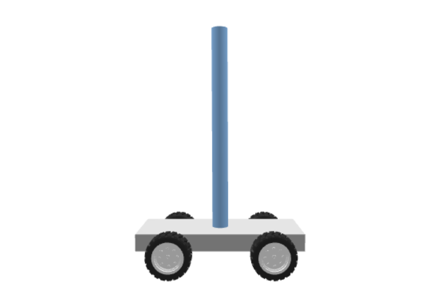

## Requirements

The following products are required to run the cartpole model:

- Bonsai [Toolbox](http://aka.ms/as/bonsai-toolbox) 0.1.0 or newer

- Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup)

## The Cartpole Model

Open `cartpole_discrete` to familiarize yourself with the model. You will not be able to run the model until you have finished configuration in later steps.

open_system('cartpole_discrete');

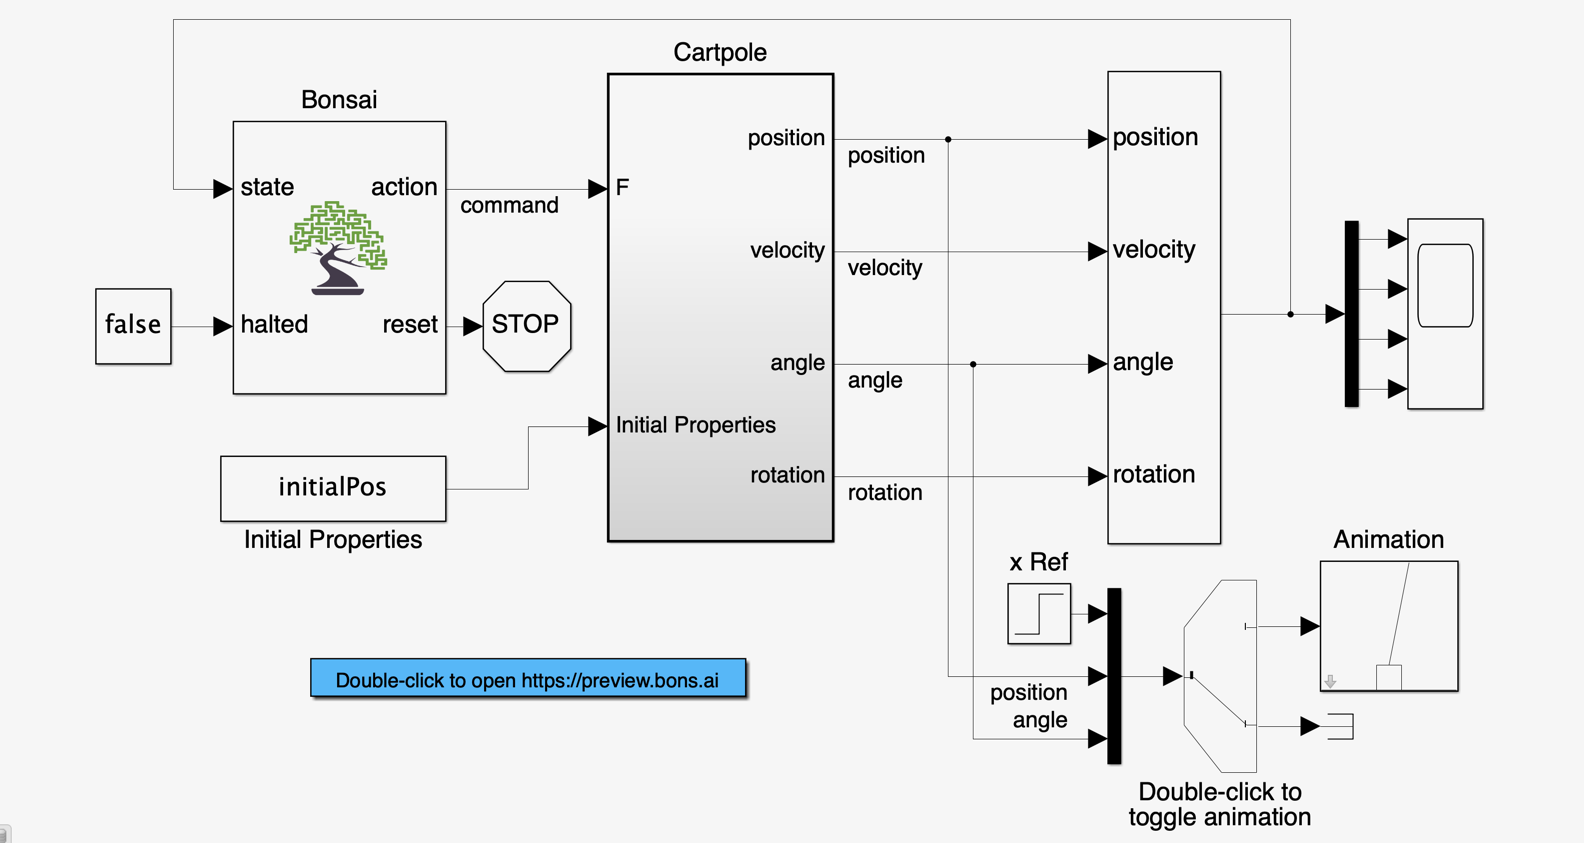

## **Create a Bonsai Brain**

### Connect to Bonsai

If you have not done so, you will need to create a Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup). 

From the [Bonsai UI](http://preview.bons.ai), you will need to capture your Bonsai **Workspace ID **and generate an **Access Key**.

### Create a Brain

In the [Bonsai UI](http://preview.bons.ai), click `+Create Brain:`

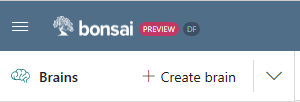

This will prompt for the type of brain to create:

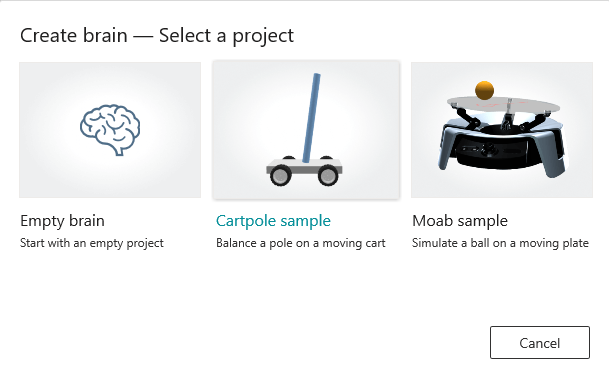

 Select `Empty brain `(not `Cartpole sample` - that is a different implementation) and enter a name in the subsequent prompt:

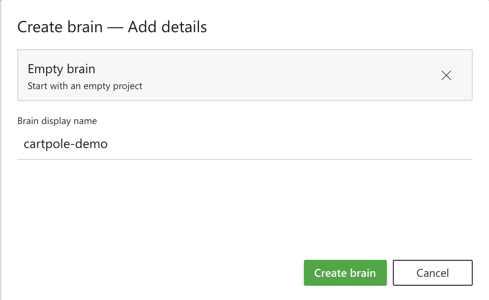

In this example, the brain is called **cartpole**`-demo``. `Click the `Create brain` button. This will create your brain and take you to the **Teach** tab:

Open `cartpole.ink` and copy/paste the inkling code into the web editor. It will auto-save after a couple seconds.

edit cartpole.ink;

## Edit Your Bonsai Configuration

### Edit `bonsaiConfig.m`

The `bonsaiConfig.m` script is where you can set up the connection between your model and the Bonsai platform.  Now open the `bonsaiConfig` file and replace 

`<your workspace here>` with your Workspace ID 

`<your access key here>` with your Access Key (*not *key ID)

% add workspace id
% add access key

edit bonsaiConfig;


You do not need to change any other values other than `workspace` and `accessKey`.

## Run Training with a Single Local Instance 

Now that the connection to Bonsai has been configured, run the `bonsaiTrain` script

bonsaiTrain;

Once you see the `Sim successfully registered` message, switch over to the [Bonsai UI](http://preview.bons.ai), click the `Train` button`. `

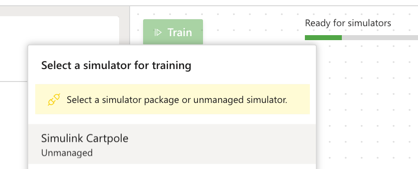

Select `Simulink - Cartpole` simulator (this assumes you left the .name value the same in bonsaiConfig). 

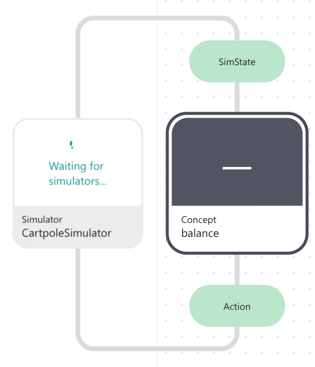

After a short time (typically <2 minutes) the sim will connect:

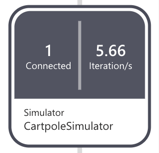

You should now see episode data streaming in the MATLAB console. To stop training, click `Stop Training `in the Bonsai UI.

**Note:** You may need to use `Ctrl+C` to break out of the simulator in MATLAB. 

## Zip, Upload and Scale Your Model

### Zip the Model

Once you have verified your model connects locally, you can close Simulink and zip the entire contents of the folder that contains the `cartpole_discrete` model and this script. It is suggested you remove your` slprj` folder and` .slxc `files before zipping up the folder contents. Call the file `cartpole.zip. `

### Upload the Model

Back in the Bonsai UI, next to `Simulators``,` click the `Add sim` button.

This will open a dialog:

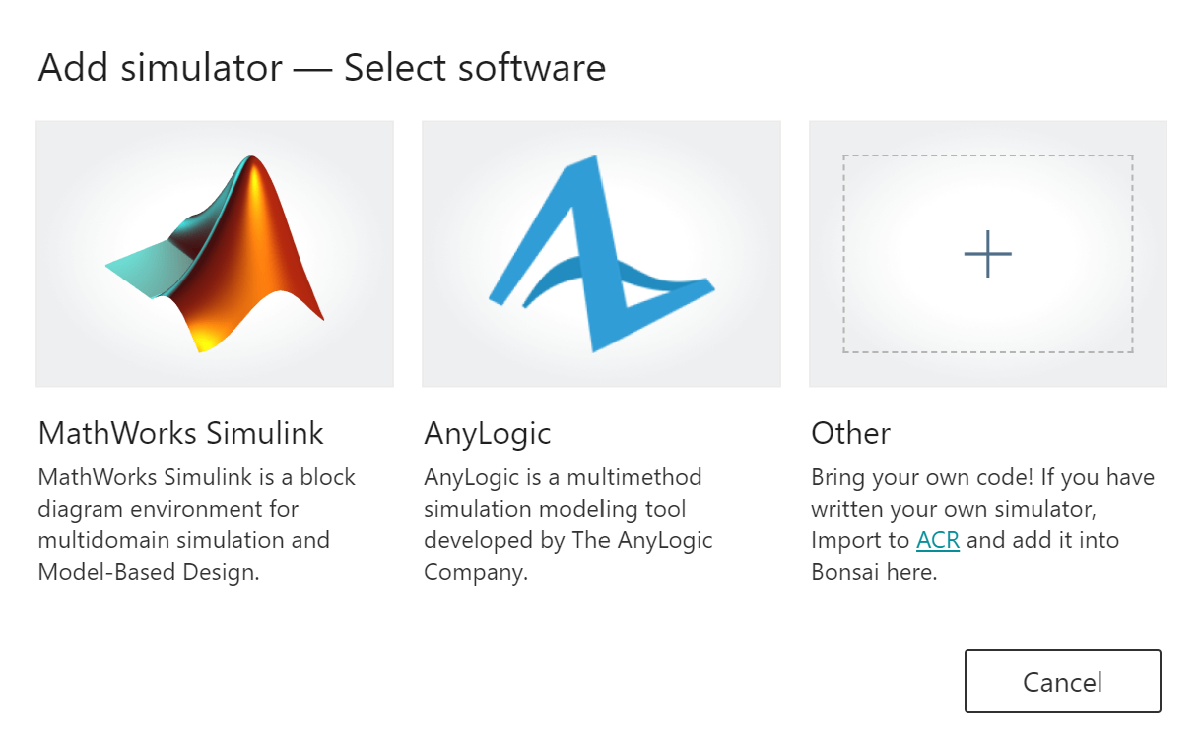

Select `MathWorks Simulink `and upload your zip file. Select or drag the `cartpole.zip `file created previously`. `

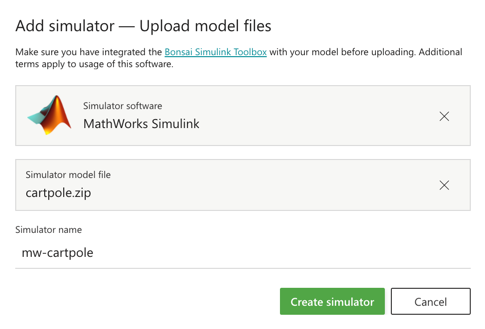

Give your simulator a name, then click `Create simulator``. `

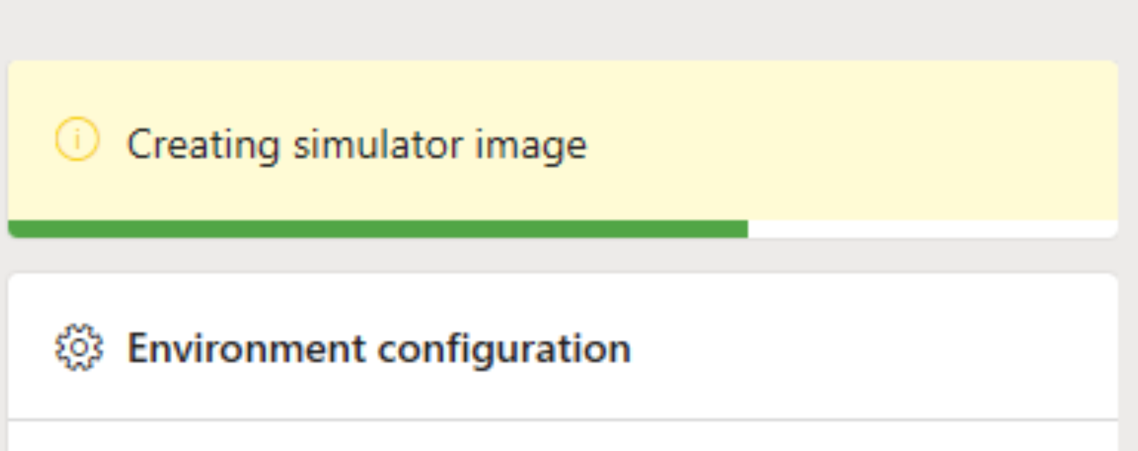

**Note: ***It may take up to 20 minutes to create the simulator image. *You will the ACR path displayed after successful creation:

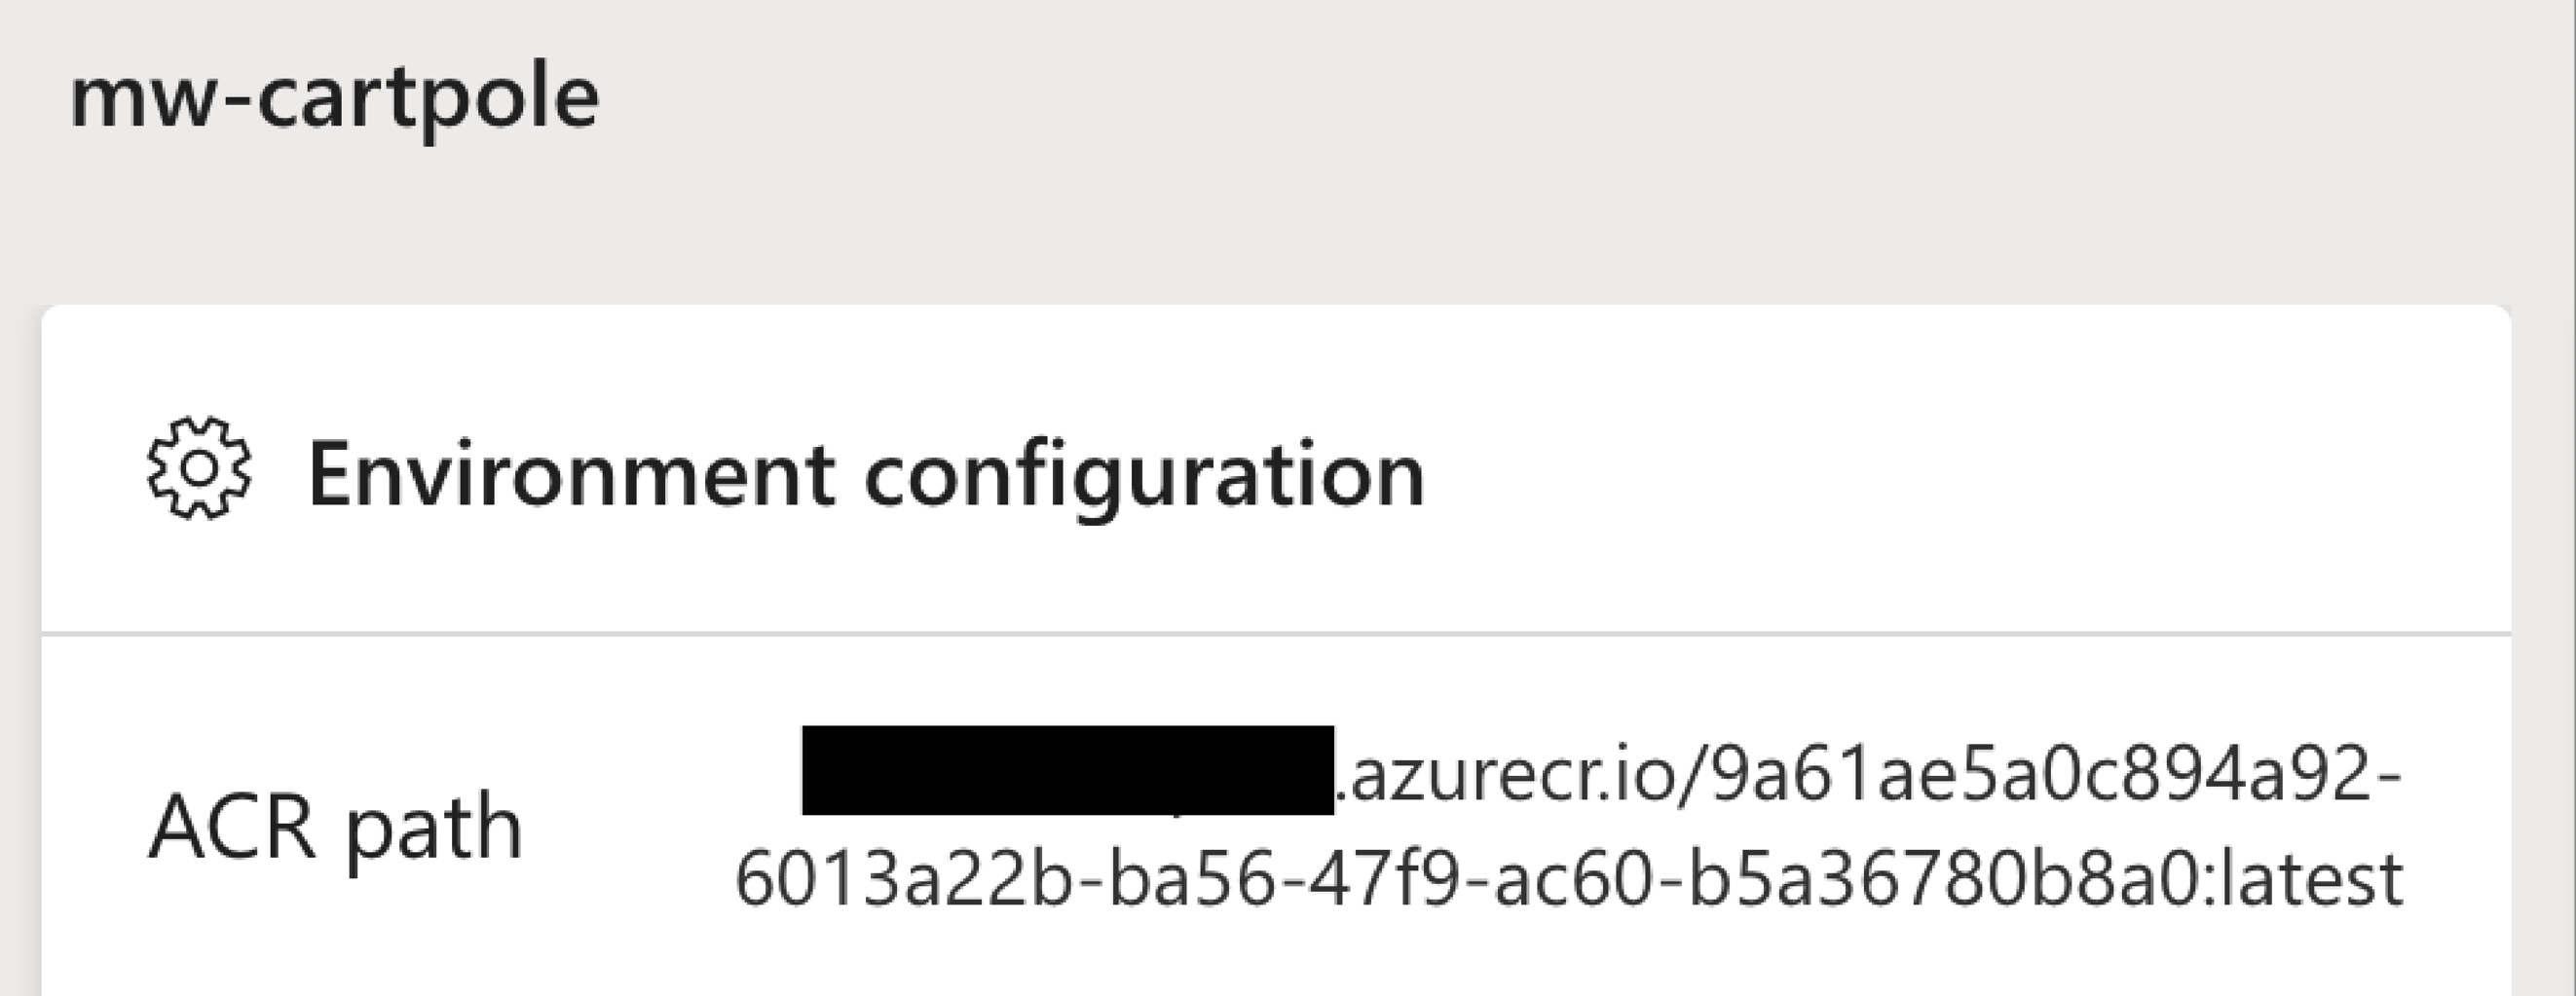

After the simulator is created you will see the new simulator appear under the `Simulators`` section.`

Now click the `Teach` tab. In the simulator definition, just after the open brackets, add a package statement using the name of the simulator you gave during the Add Simulator dialog above.

### Scale Your Training

Now click the `Train` button for your brain. This will create several instances (from 1-50) using the uploaded model to train your brain. As you give your brain time to learn, you should see brain performance improve.

**Note: **It may take up to 10 minutes for your simulators to connect.

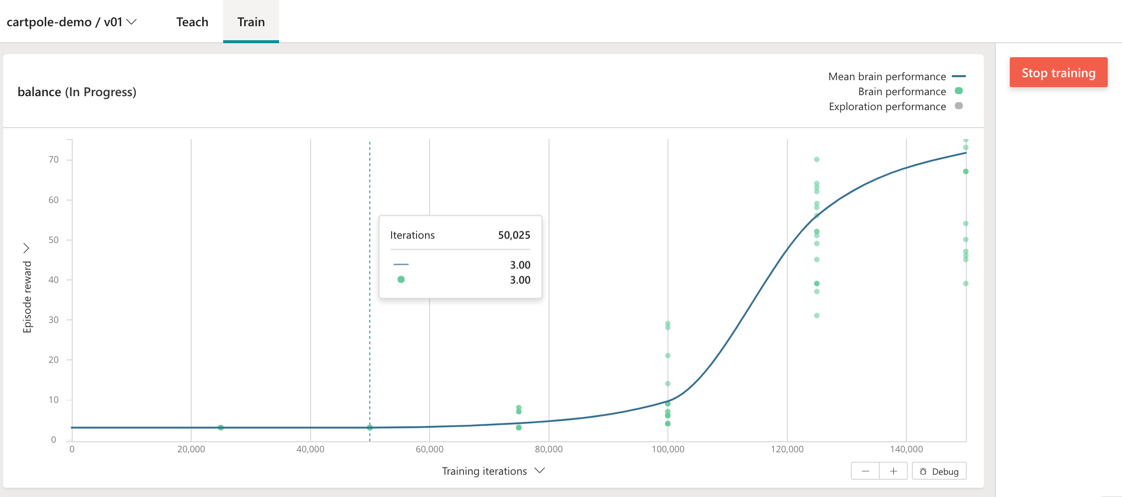

Once you see performance converge, click `Stop Training`.

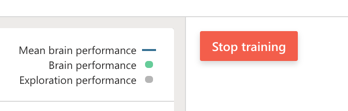

## Assessing Brain Performance

Assessment allows you to test the performance of a trained brain while still hosting that brain in the Bonsai platform. After training your brain(s) you will want to assess their performance. Configure assessment by running:

bonsaiAssess;

Open the `cartpole_discrete` model and click the `Run` button. You will see a pop-up prompting you to start assessment in the Bonsai UI:

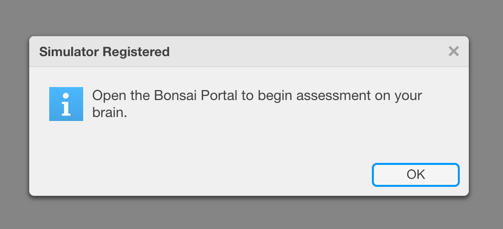

Go to the [Bonsai UI](http://preview.bons.ai) and click the `Start Assessment `button.

Select the `Simulink - Cartpole` simulator. Your local model will iterate using the brain in assessment mode. Click `View Diagnostics` in your Simulink window to view Bonsai logs. If you receive the message `Last event was Unregister, done requesting events `then you may need to increase the timeout value in bonsaiConfig.

If you'd like to see a cartpole visualization during assessment, double-click the variant sink in your model to enable it before running assessment: